# Validation of Physics-Based Image Systems Simulation with 3D Scenes

## Figure 10

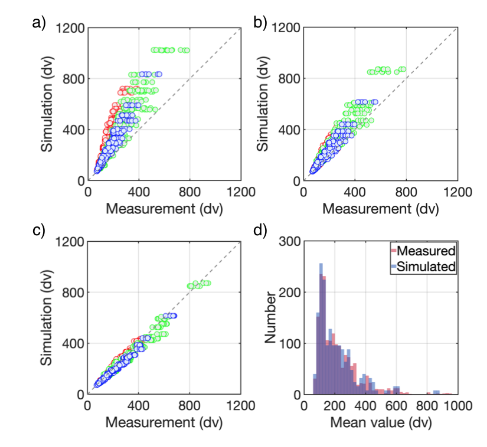

Fig. 10. Validation of estimated color filter QE. The scatter plots compare the mean simulated and measured value for the 24 patches under three different illuminants. The color of each point is a measurement in the R, G or B channels. Panels a-c show these fits. (a) Without lens vignetting, channel gain, or cross-talk correction the fits are quite poor. (b) Correcting for lens vignetting alone improves the fit. (c) Correcting for lens vignetting, channel gain and cross-talk places all the points near the identity line. (d) The histogram shows the distribution of measured and simulated digital values; most of the comparisons are based on relatively small digital values.

%%
ieInit;

%% Initialization
tmp = load('p4aLensVignet_dc_p55_pos1.mat', 'pixel4aLensVignetSlope');
vignetting = tmp.pixel4aLensVignetSlope;

%
qeDir = fullfile(cboxRootPath, 'data', 'measurement', 'QEcalibration');
%% First check the accuracy in the middle center with everything on 
% Read in mean meas
illuminantType = {'A', 'day', 'cwf'};
pos = {'midcenter'};
cornerPointsMeas = {[1858 1408 2229 1656],...
                    [1858 1408 2229 1656],...
                    [1858 1408 2229 1656]};
nFrames = numel(illuminantType) * numel(pos);
imgNames = cell(1, nFrames);
illuminants = cell(1, nFrames);
% Counter
cnt = 1;
for ii=1:numel(illuminantType)
    thisIllu = illuminantType{ii};
    
    curIlluDir = fullfile(qeDir, thisIllu);
    
    for jj=1:numel(pos)
        thisDngFile = dir(fullfile(curIlluDir, pos{jj}, '*.dng'));
        imgNames{cnt} = fullfile(curIlluDir, pos{jj},thisDngFile(1).name);
        illuminants{cnt} = thisIllu;
        cnt = cnt + 1;
    end
end

% Get rgb mean in mid center
rgbMeanMeasMidCenter = zeros(nFrames * 24, 3);
for ii=1:numel(imgNames)
    thisCropMeas = cornerPointsMeas{ii};
    thisIllu = illuminants{ii};
    % Get the mean rgb for this sensor
    [thisSensorMeas, thisInfo, thisRGBMeanMeas, ~] = cbMccChipsDV(imgNames{ii},...
                                                              'corner point', thisCropMeas,...
                                                              'vignetting', vignetting);
    rgbMeanMeasMidCenter((ii-1) * 24+1:ii*24,:) = thisRGBMeanMeas;
end

Black border
Black border
Black border




%% Calculate simulate signals
% Precompute the illumination scene and oi
wave = 390:10:710;
lightNameA   = 'illA-20201023.mat'; % Tungsten (A)
lightNameCWF = 'illCWF-20201023.mat'; % CWF
lightNameDay = 'illDay-20201023.mat'; % Daylight
patchSize = 32;
[sceneA, oiA] = cbMccSceneOISim('illuminant', lightNameA, 'wave', wave,...
                                'patch size', patchSize);
[sceneCWF, oiCWF] = cbMccSceneOISim('illuminant', lightNameCWF, 'wave', wave,...
                                'patch size', patchSize);       
[sceneDay, oiDay] = cbMccSceneOISim('illuminant', lightNameDay, 'wave', wave,...
                                'patch size', patchSize);
                            
cornerPointsSim = [165 160 1089 770];
sensorSimCor = cbDNGRead(imgNames{3}, 'demosaic', false);
% Get the black level
blkLvl = sensorGet(sensorSimCor, 'black level');
[~, rgbMeanACor, ~] = cbMccSensorSim(oiA, sensorSimCor, cornerPointsSim);

Black border


[~, rgbMeanDayCor, ~] = cbMccSensorSim(oiDay, sensorSimCor, cornerPointsSim);

Black border


[~, rgbMeanCWFCor, ~] = cbMccSensorSim(oiCWF, sensorSimCor, cornerPointsSim);

Black border


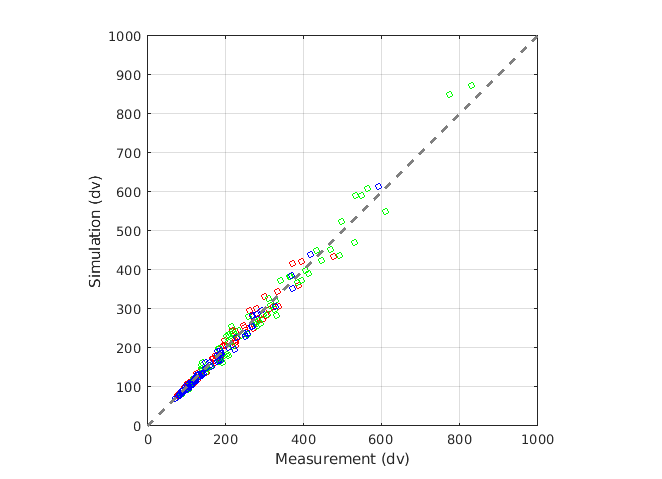


rgbMeanSimCorMidCenter = [rgbMeanACor;rgbMeanDayCor;rgbMeanCWFCor];
% Make sure the simulated sensor data match the measurement
ieNewGraphWin; 
hold all;
plot(rgbMeanMeasMidCenter(:,1) + blkLvl, rgbMeanSimCorMidCenter(:,1)+ blkLvl,'ro', 'MarkerSize', 5); 
plot(rgbMeanMeasMidCenter(:,2)+ blkLvl, rgbMeanSimCorMidCenter(:,2)+ blkLvl,'go', 'MarkerSize', 5);
plot(rgbMeanMeasMidCenter(:,3)+ blkLvl, rgbMeanSimCorMidCenter(:,3)+ blkLvl,'bo', 'MarkerSize', 5);
axis square; box on;
identityLine;
xlabel('Measurement (dv)'); ylabel('Simulation (dv)');


% Now compute the sensor response without color filter correction
sensorSimNoCor = cbDNGRead(imgNames{3}, 'demosaic', false, 'transcolorfilter', false);
[~, rgbMeanANoCor, ~] = cbMccSensorSim(oiA, sensorSimNoCor, cornerPointsSim);

Black border


[~, rgbMeanDayNoCor, ~] = cbMccSensorSim(oiDay, sensorSimNoCor, cornerPointsSim);

Black border


[~, rgbMeanCWFNoCor, ~] = cbMccSensorSim(oiCWF, sensorSimNoCor, cornerPointsSim);

Black border


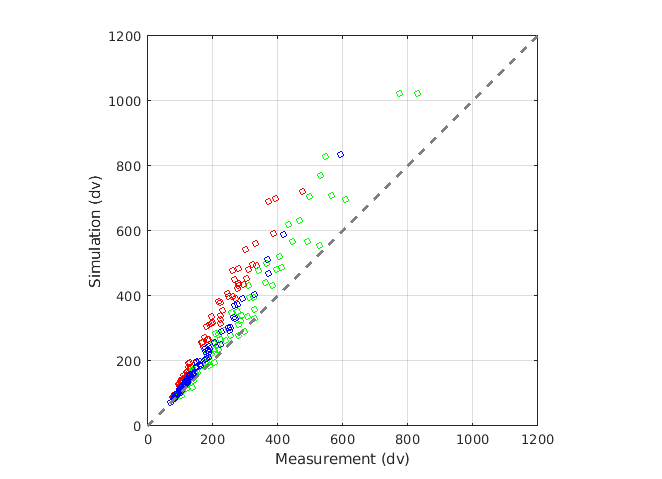


rgbMeanSimNoCorMidCenter = [rgbMeanANoCor;rgbMeanDayNoCor;rgbMeanCWFNoCor];
% Make sure the simulated sensor data w/o correction DOES NOT match the measurement
ieNewGraphWin; 
hold all;
plot(rgbMeanMeasMidCenter(:,1) + blkLvl, rgbMeanSimNoCorMidCenter(:,1)+ blkLvl,'ro','MarkerSize', 5); identityLine;
plot(rgbMeanMeasMidCenter(:,2)+ blkLvl, rgbMeanSimNoCorMidCenter(:,2)+ blkLvl,'go','MarkerSize', 5); identityLine;
plot(rgbMeanMeasMidCenter(:,3)+ blkLvl, rgbMeanSimNoCorMidCenter(:,3)+ blkLvl,'bo','MarkerSize', 5); identityLine;
axis square; box on;
identityLine;
xlabel('Measurement (dv)'); ylabel('Simulation (dv)');


illuminantType = {'A', 'cwf', 'day'};
pos = {'topleft', 'topcenter', 'topright',...
       'midleft', 'midright',...
       'botleft', 'botcenter', 'botright'};
cornerPointsMeas = {[1009 474 1434 766],...
                    [1884 511 2300 788],...
                    [3086 572 3479 833],...
                    [970 1410 1333 1656],...
                    [3165 1410 3553 1664],...
                    [1117 2117 1460 2345],...
                    [1831 2113 2186 2351],...
                    [3142 2148 3519 2395],...
                    [1009 474 1434 766],...
                    [1884 511 2300 788],...
                    [3086 572 3479 833],...
                    [970 1410 1333 1656],...
                    [3165 1410 3553 1664],...
                    [1117 2117 1460 2345],...
                    [1831 2113 2186 2351],...
                    [3142 2148 3519 2395],...
                    [1009 474 1434 766],...
                    [1884 511 2300 788],...
                    [3086 572 3479 833],...
                    [970 1410 1333 1656],...
                    [3165 1410 3553 1664],...
                    [1117 2117 1460 2345],...
                    [1831 2113 2186 2351],...
                    [3142 2148 3519 2395]};
                
nFrames = numel(illuminantType) * numel(pos);
imgNames = cell(1, nFrames);
illuminants = cell(1, nFrames);
% Counter
cnt = 1;
for ii=1:numel(illuminantType)
    thisIllu = illuminantType{ii};
    
    curIlluDir = fullfile(qeDir, thisIllu);
    
    for jj=1:numel(pos)
        thisDngFile = dir(fullfile(curIlluDir, pos{jj}, '*.dng'));
        imgNames{cnt} = fullfile(curIlluDir, pos{jj},thisDngFile(1).name);
        illuminants{cnt} = thisIllu;
        cnt = cnt + 1;
    end
end

%% Step A: No vigneeting, color, BRDF correction
% No lens vignetting correction
cornerPointsSim = [147 115 1086 737];
[~, ~, ~, rgbMeanMeas8PosNoVig] = cbQEAnalysis(imgNames, illuminants,...
                        cornerPointsMeas, cornerPointsSim,...
                        [], 'method', 'nonnegative');

Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the 

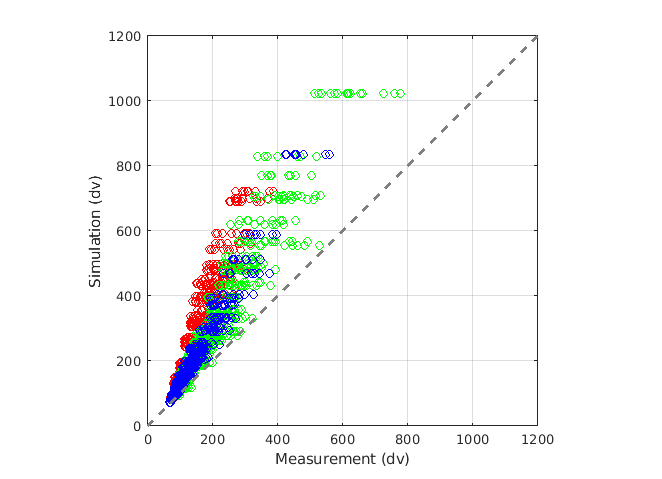

% ieNewGraphWin; plot(rgbMeanMeas8Pos(193:216,:), rgbMeanMeas8Pos(217:217+24-1,:),'o'); identityLine                 
% Compare it with no color corr sensor sim
tmpA = repmat(rgbMeanANoCor, [8,1]);
tmpDay = repmat(rgbMeanDayNoCor, [8,1]);
tmpCWF = repmat(rgbMeanCWFNoCor, [8, 1]);
rgbMeanSimNoCorRep = [tmpA; tmpCWF; tmpDay];
% Figure: no vignetting, color or BRDF correction
ieNewGraphWin;
hold all
plot(rgbMeanMeas8PosNoVig(:,1)+ blkLvl, rgbMeanSimNoCorRep(:,1)+ blkLvl, 'ro');
plot(rgbMeanMeas8PosNoVig(:,2)+ blkLvl, rgbMeanSimNoCorRep(:,2)+ blkLvl, 'go');
plot(rgbMeanMeas8PosNoVig(:,3)+ blkLvl, rgbMeanSimNoCorRep(:,3)+ blkLvl, 'bo');
identityLine; grid on; axis square; box on;
xlabel('Measurement (dv)'); ylabel('Simulation (dv)');

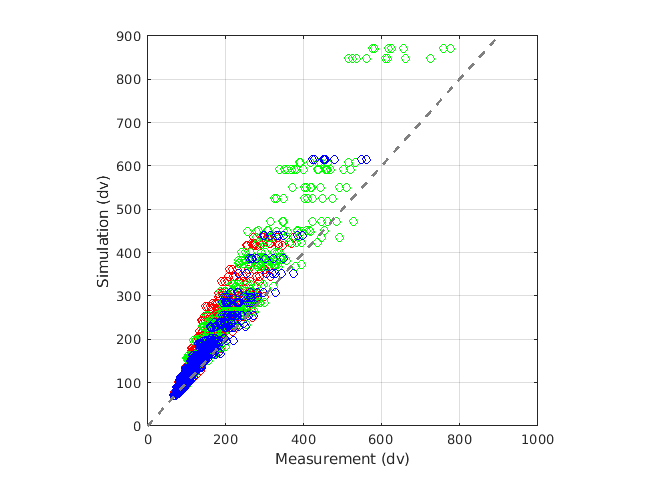


%% Step B: add color filter correction
tmpA = repmat(rgbMeanACor, [8,1]);
tmpDay = repmat(rgbMeanDayCor, [8,1]);
tmpCWF = repmat(rgbMeanCWFCor, [8, 1]);
rgbMeanSimCorRep = [tmpA; tmpCWF; tmpDay];
% Figure: color correction, no vignetting or BRDF correction
ieNewGraphWin;
hold all
plot(rgbMeanMeas8PosNoVig(:,1)+ blkLvl, rgbMeanSimCorRep(:,1)+ blkLvl, 'ro');
plot(rgbMeanMeas8PosNoVig(:,2)+ blkLvl, rgbMeanSimCorRep(:,2)+ blkLvl, 'go');
plot(rgbMeanMeas8PosNoVig(:,3)+ blkLvl, rgbMeanSimCorRep(:,3)+ blkLvl, 'bo');
identityLine; grid on; axis square; box on
xlabel('Measurement (dv)'); ylabel('Simulation (dv)');


%% Step C: add lens vignetting correction
% Add lens vignetting correction
[~, ~, ~, rgbMeanMeas8PosVig] = cbQEAnalysis(imgNames, illuminants,...
                        cornerPointsMeas, cornerPointsSim,...
                        vignetting, 'method', 'nonnegative');

Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border
Black border

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the 

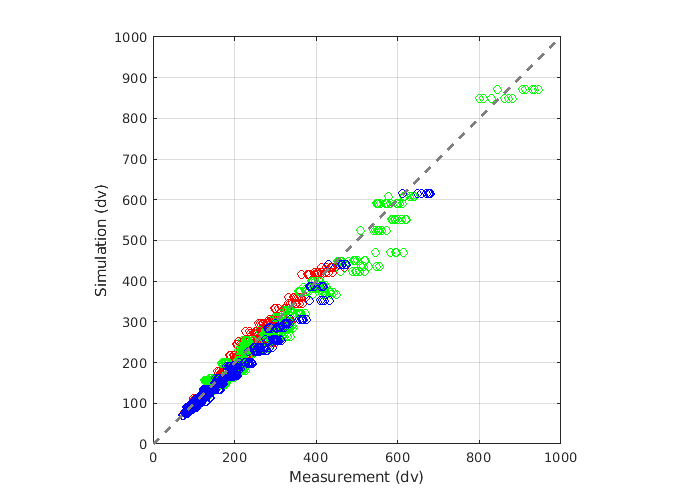


% Figure: vignetting and color correction, no or BRDF correction
ieNewGraphWin;
hold all
plot(rgbMeanMeas8PosVig(:,1)+ blkLvl, rgbMeanSimCorRep(:,1)+ blkLvl, 'ro');
plot(rgbMeanMeas8PosVig(:,2)+ blkLvl, rgbMeanSimCorRep(:,2)+ blkLvl, 'go');
plot(rgbMeanMeas8PosVig(:,3)+ blkLvl, rgbMeanSimCorRep(:,3)+ blkLvl, 'bo');
identityLine; grid on; axis square; box on
xlabel('Measurement (dv)'); ylabel('Simulation (dv)');

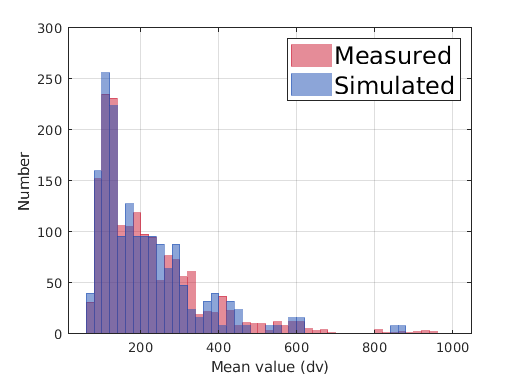


%% Step D: hist
edges = 60:20:1000;

ieNewGraphWin;
nBins = 30; alpha = 0.5;
hMeas = histogram(rgbMeanMeas8PosVig(:) + blkLvl,edges);
hMeas.FaceColor = [0.8 0.1 0.2];
hMeas.FaceAlpha = alpha;
hMeas.EdgeColor = hMeas.FaceColor;
hMeas.EdgeAlpha = hMeas.FaceAlpha;
hold on;

hSim = histogram(rgbMeanSimCorRep(:) + blkLvl,edges);
hSim.FaceColor = [0.1 0.3 0.7];
hSim.FaceAlpha = alpha;
hSim.EdgeColor = hSim.FaceColor;
hSim.EdgeAlpha = hSim.FaceAlpha;
grid on
xlabel('Mean value (dv)');
ylabel('Number')
lgn = legend('Measured','Simulated');
lgn.FontSize = 18;